# Supervised Learning - Week 3 / Part 2

## Cost Function for Logistic Regression

It is important to note that the cost function gives us a way to measure how well a specific algorithm fits the training data. Therefore, we can use that information to choose better parameters. We will see shortly why a squared error cost function is not an ideal cost function for logistic regression algortihm and we will find a better cost function for the classification task.

The following data would be a potential dataset for a logistic regression task

tumorSize = [10; 2; 5; 12];
patientAge = [52; 73; 55; 49];
isMalignant = [1; 0; 0; 1];
T = table(tumorSize,patientAge,isMalignant);
T.Properties.VariableNames = ["Tumor Size (cm)";"Patient's Age";"Is Malignant?"];
disp(T)

    Tumor Size (cm)    Patient's Age    Is Malignant?
    _______________    _____________    _____________

          10                52                1      
           2                73                0      
           5                55                0      
          12                49                1      



Similar to the previous notations we will use $i \in \{ 1,2,\cdots,m \}$, where $m$ denotes the number of training examples. Each training examples have number of features, $j \in \{ 1,2,\cdots,n \}$, where $n$ is the number of features. The each feature is labelled as $x_1, x_2,\cdots,x_n$ and the target label $y$ takes only two values either 0 or 1. Finally, the logistic regression is defined by the following expression


$$f_{\mathbf{w},b}( \mathbf{x} ) = g(z) = g(\mathbf{x}\mathbf{w}+b)
= \frac{1}{1+e^{-\left(\mathbf{x}\mathbf{w}+b\right)}}$$


- Given the training set above how can we choose the parameters $\mathbf{w}$ and $b$?

Recall from the linear regression that the squared error cost was defined by

$J(\mathbf{w},b) = \frac{1}{m}\sum^{m}_{i=1} \frac{1}{2} \left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) - y^{(i)} \right)^2$, where $f_{\mathbf{w},b}(\mathbf{x}^{(i)}) = \mathbf{x}^{(i)}\mathbf{w} + b$

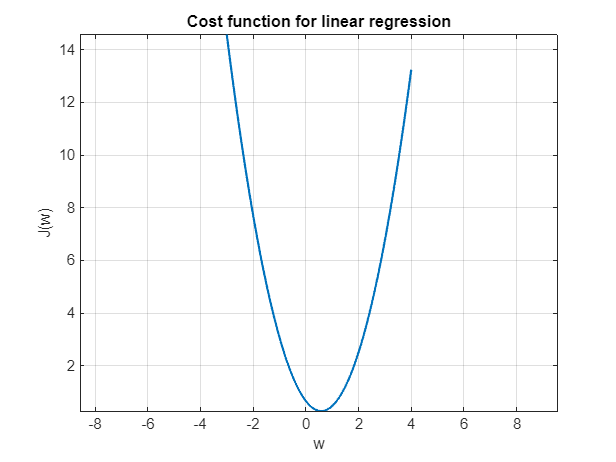

[w,J] = costFunction("linear-regression");
plot(w,J,'LineWidth',1.5)
grid on
xlabel('w')
ylabel('J(w)')
title("Cost function for linear regression")
axis equal

Note from the above plot and expression that the cost function is a **convex function** for the linear regression task. Therefore, the gradient descent algorithm will get closer to the global minimum point with the each step. If we try to use the same cost function for the logistic regression task

$J(\mathbf{w},b) = \frac{1}{m}\sum^{m}_{i=1} \frac{1}{2} \left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) - y^{(i)} \right)^2$, where $f_{\mathbf{x},b}(\mathbf{x}^{(i)}) = \frac{1}{1 + e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)}}$

Let's also plot the above expression

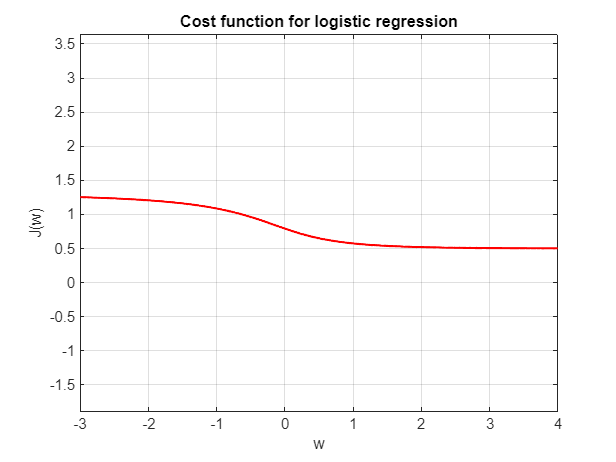

[w,J] = costFunction("logistic-regression");
plot(w,J,'r','LineWidth',1.5)
grid on
xlabel('w')
ylabel('J(w)')
title("Cost function for logistic regression")
axis equal

- As can be seen from the above plots, **the squared error cost function is a non-convex function** with respect to the parameter $w$ in logistic regression task. This also means that if we use gradient descent to find the global minimum of the cost function surface the algorithm will likely to be stuck in a local minima and will yield a sub-optimal solution.

We now know that the squared error cost function is not a good choice for the classification tasks. We will look for a different cost function that would make the cost function surface w.r.t the parameter $w$ convex so that the gradient descent algorithm will guarantee us the convergence to the global minimum.

- Let's call the term inside the cost function as **loss**, that is defined **for a single training example**: $L(f_{\mathbf{w},b}( \mathbf{x}^{(i)}), y^{(i)})
= \frac{1}{2} \left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) - y^{(i)} \right)^2$, which is a function of a prediction of the learning algorthm ($f_{\mathbf{w},b}( \mathbf{x}^{(i)})$) and the true label ($y^{(i)}$). We will see shortly that by choosing different form for the cost function will allow us to keep the overall cost function and have convex function w.r.t to the parameters.

- The loss function for the logistic regression could be given by


$$L(f_{\mathbf{w},b}( \mathbf{x}^{(i)}), y^{(i)}) =
\left\{
    \begin{array}{lr}
        -\log\left( f_{\mathbf{w},b}( \mathbf{x}^{(i)}) \right), & \text{if } y^{(i)} = 1  \\
        -\log\left( 1 - f_{\mathbf{w},b}( \mathbf{x}^{(i)}) \right), & \text{if } y^{(i)} = 0
    \end{array}$$


Let's take a look why this cost function makes sense

### Case y = 1

Let's consider the first case, which is $y^{(i)} = 1$, and plot it to gain some intuition. Remember that the loss function measures how well you are doing on one training example, where by summing up all the examples you have you will get the cost function which shows how well you are doing in the entire training set.

If we plot $-\log\left( f_{\mathbf{w},b}( \mathbf{x}^{(i)}) \right)$:

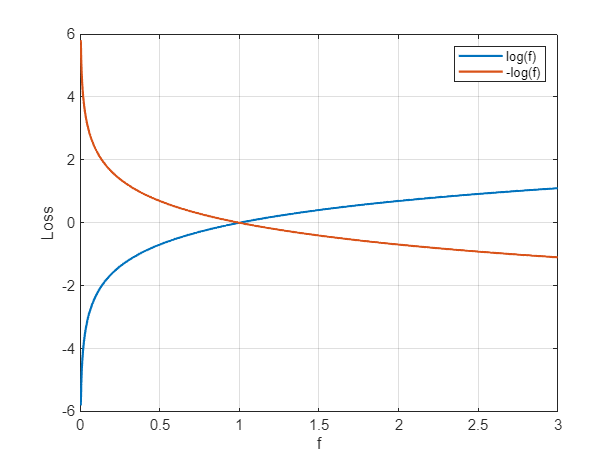

f = linspace(0,3,1e3);
L1 = log(f);
L2 = -log(f);
plot(f,L1,'LineWidth',1.5)
hold on
plot(f,L2,'LineWidth',1.5)
hold off
xlabel('f')
ylabel('Loss')
grid on
legend("log(f)","-log(f)")

Note that $f$is output of the logistic regression $f_{\mathbf{x},b}(\mathbf{x}^{(i)}) = \frac{1}{1 + e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)}}$ and its output is always between 0 and 1. Therefore,

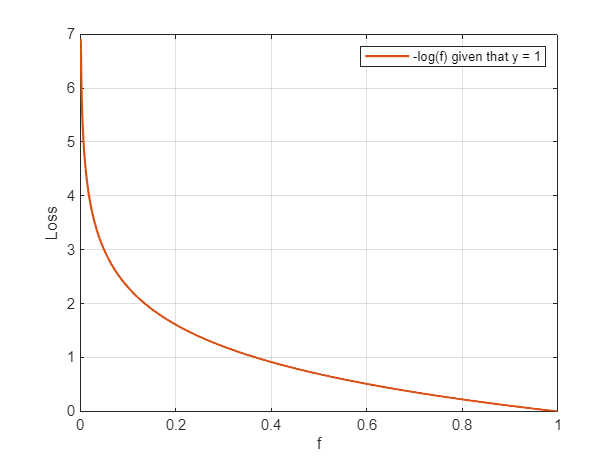

f = linspace(0,1,1e3);
L = -log(f);
plot(f,L,'LineWidth',1.5,'Color',"#D95319")
xlabel('f')
ylabel('Loss')
grid on
legend("-log(f) given that y = 1")

- If the algorithm predicts a value close to 1 and the true label is also 1, the loss function output will be close to 0.

- If the algorithm predicts a value close to 0 and the true label is 1, the loss function output will be close to a very large value (limit goes to $+\infty$).

Therefore, when $y=1$, the loss function incentivizes to make more accurate prediction since the loss is lowest when the $f_{\mathbf{x},b}(\mathbf{x}^{(i)})$ predicts close to the true label $y^{(i)}$.

### Case y = 0

Let's also look at the case when the true label $y^{(i)}=0$, by plotting $-\log\left( 1 - f_{\mathbf{w},b}( \mathbf{x}^{(i)}) \right)$:

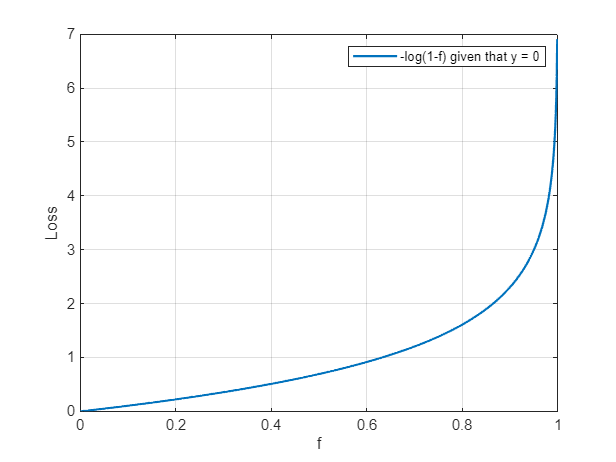

f = linspace(0,1,1e3);
L = -log(1-f);
plot(f,L,'LineWidth',1.5)
xlabel('f')
ylabel('Loss')
grid on
legend("-log(1-f) given that y = 0")

- In this plot corresponding to $y = 0$, when f is close to zero the loss value is also very close to 0, which means that if the prediction and the actual value are close, the loss function outputs zero - no penalty.

- When f is close to 1, the loss value is approaching to the $+\infty$, which means that if the prediction and the actual value are not matching, the loss function outputs a very large value to penalize the model. Larger the prediction error gets the loss gets bigger and bigger.

The further the prediction $f_{\mathbf{x},b}(\mathbf{x}^{(i)})$ is from the the target $y^{(i)}$, the higher the loss (penalty)!

Therefore the cost function for the logistic regression task becomes,


$$J(\mathbf{w},b) = \frac{1}{m} \sum_{i=1}^{m} L \left( f_{\mathbf{w},b} (\mathbf{x}^{(i)}), y^{(i)}  \right)$$


where, $L\left( y^{(i)}, f_{\mathbf{w},b}( \mathbf{x}^{(i)}) \right) = 
\left\{
    \begin{array}{lr}
        -\log\left( f_{\mathbf{w},b}( \mathbf{x}^{(i)}) \right), & \text{if } y^{(i)} = 1  \\
        -\log\left( 1 - f_{\mathbf{w},b}( \mathbf{x}^{(i)}) \right), & \text{if } y^{(i)} = 0
    \end{array}$

It turns out that with the selection of such loss function makes the overall cost function convex. Thus, you can rely on gradient descent algorithm to find the global minimum.

### An alternative way of deriving the loss function for classification:

It is important to note that ideally we want the following loss function:

What could be a good alternative for such a loss function $L$?

- Both exponential and logarithmic functions would be a good candidate.

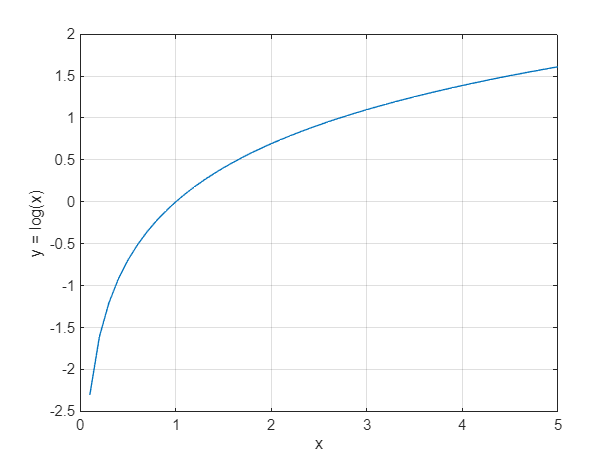

x = 0.1:0.1:5;
plot(x,log(x))
xlabel('x')
ylabel('y = log(x)')
grid on

We can focus on the logarithmic function's behaviour between the interval $[0 \quad 1]$. Therefore,

- $-\log(x) = \infty $, if $x = 0$,

- $-\log(x) = 0$, if $x = 1$

By combining the table and the expression above,

$L\left( y^{(i)}, f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) = -\log\left( 1-|y^{(i)} - f_{\mathbf{w},b}(\mathbf{x}^{(i)})| \right)$, which will correspond to the following piece-wise expression:


$$L\left( y^{(i)}, f_{\mathbf{w},b}( \mathbf{x}^{(i)}) \right) = 
\left\{
    \begin{array}{lr}
        -\log\left( f_{\mathbf{w},b}( \mathbf{x}^{(i)}) \right), & \text{if } y^{(i)} = 1  \\
        -\log\left( 1 - f_{\mathbf{w},b}( \mathbf{x}^{(i)}) \right), & \text{if } y^{(i)} = 0
    \end{array}$$


Alternatively the above expressions could also be represented by,

$L\left( y^{(i)}, f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) = -(1-y^{(i)}) \log \left( 1 - f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) - y^{(i)}\log \left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right)$. Or,


$$L\left( y^{(i)}, f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) = - \bigg(
(1-y^{(i)}) \log \left( 1 - f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) + y^{(i)}\log \left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \bigg) \quad \diamondsuit$$


- Loss function measures how well you are doing in one training example.

- Cost function measures how well yo are doing in the entire dataset.

## Lab: Logistic Loss

Let's visualize the squared error cost function w.r.t. the parameters $w$ and $b$.

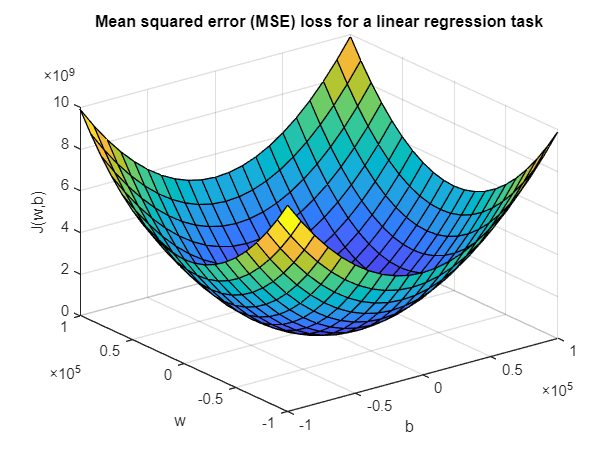

% Load the regression dataset (m = 47, n = 2)
% Features (X): size (sq. feet) / # of bedrooms
% Targets (y): price ($)

% Load the dataset
% Note that we will only be using the size (in square feet) feature of the
% input for this application
data = load('simpleRegressionDataset.mat');
X = data.X(:,1);
y = data.y;
X_norm = zScoreNormalization(X); % z-score normalization
y_norm = zScoreNormalization(y); % z-score normalization

w_vec = -1e5:1e4:1e5; % weights
b_vec = -1e5:1e4:1e5; % bias
f = [];
J = [];

for idxw = 1:numel(w_vec)
    w = w_vec(idxw);
    for idxb = 1:numel(b_vec)
        b = b_vec(idxb);
    
        % The logistic regression and cost function calculations yield a
        % vector for each w and b
        f{idxw,idxb} = w.*X_norm + b;
        J(idxw,idxb) = ( 1/(2*length(X_norm)) )*sum( (f{idxw,idxb}-y_norm).^2 );
    end
end

figure
surf(b_vec,w_vec,J)
xlabel('b')
ylabel('w')
zlabel('J(w,b)')
title('Mean squared error (MSE) loss for a linear regression task')

Since the mean squared error (MSE) loss function works well for the linear regression tasks, it is natural to think about implementing it in the logistic regression tasks as well. Let's visualize the loss function surface when the MSE loss is implemented into a logistic regression task. We will be using a real cancer dataset for this application.

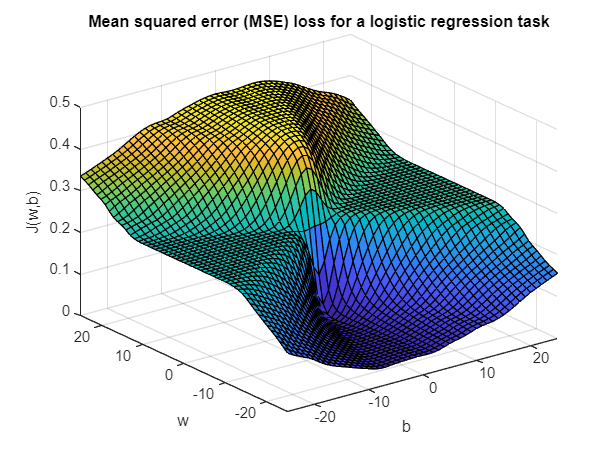

% Load the classification dataset (m = 155, n = 3)
% Targets y: 0-male, 1-female
% Features X: height / hand-length / foot-length
data = load('simpleClassificationDataset.mat');
X = data.X(:,1);
% Normalize the input feature. Note that we will only be using the height.
% Unlike the regression task the labels in classification doesn't need to
% be normalized since the range for the classification labels is [0 1].
X_norm = zScoreNormalization(X);
y = data.y;

w_vec = -25:1:25; % weights
b_vec = -25:1:25; % bias
f = [];
J = [];

for idxw = 1:numel(w_vec)
    w = w_vec(idxw);
    for idxb = 1:numel(b_vec)
        b = b_vec(idxb);
    
        % The logistic regression and cost function calculations yield a
        % vector for each w and b
        f{idxw,idxb} = 1./(1 + exp( -(w.*X_norm+b) ));
        J(idxw,idxb) = ( 1/(2*length(X_norm)) )*sum( (f{idxw,idxb}-y).^2 );
    end
end

figure
surf(b_vec,w_vec,J)
xlabel('b')
ylabel('w')
zlabel('J(w,b)')
title('Mean squared error (MSE) loss for a logistic regression task')

It is important to note from the above plot that the surface for the logistic regression task is not as smooth as the "soup bowl" shape of the linear regression task! Logistic regression requires a cost function more suitable to its non-linear nature. Definition of the "cost function" starts with the definition of the "loss function":

- **Loss: Is a measure that how well the classification algorithm does based on a single training example.**

- **Cost: Is a measure that how well the classification algorithm does based on the entire training set.**

Let's define the loss function first

$L(f_{\mathbf{w},b}( \mathbf{x}^{(i)}), y^{(i)})
\left\{
    \begin{array}{lr}
        -\log\left( f_{\mathbf{w},b}( \mathbf{x}^{(i)}) \right), & \text{if } y^{(i)} = 1  \\
        -\log\left( 1 - f_{\mathbf{w},b}( \mathbf{x}^{(i)}) \right), & \text{if } y^{(i)} = 0
    \end{array}$, where this expression could be simplified to the following form:


$$L(f_{\mathbf{w},b}( \mathbf{x}^{(i)}), y^{(i)})
=  -y^{(i)}\log\left( f_{\mathbf{w},b}( \mathbf{x}^{(i)}) \right)  - (1-y^{(i)})\log\left( 1-f_{\mathbf{w},b}( \mathbf{x}^{(i)}) \right)$$


where the above expression is called **binary cross-entropy loss** function. It is important to note that the loss function above consists of two seperate curves; one for each label $y^{(i)} = 1$ and $y^{(i)} = 0$. When, both expressions are combined into a single expression it becomes quite useful as it returns very large values (approaches to $+\infty$) when the model's prediction is far from the actual label and very small values (approaches to $0$) when the model's predictions are accurate.

Let's take a look at the solution space by using this new loss function, we will be using the same cancer dataset as the previous cost function plotting.

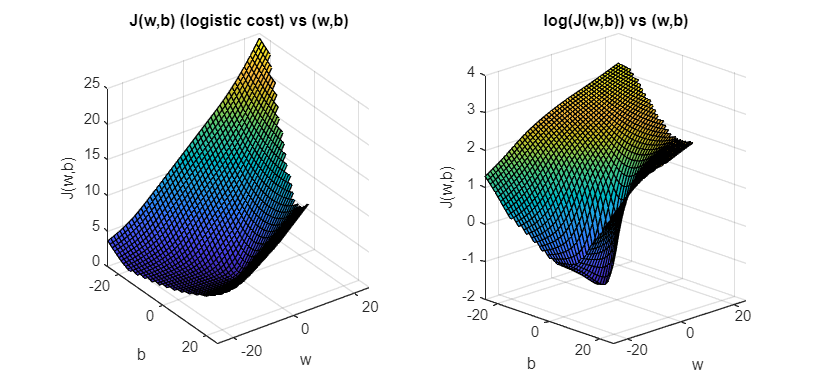

% Load the classification dataset (m = 155 (# of samples), n = 3 (# of features))
% Targets y: 0-male, 1-female
% Features X: height / handLength / footLength
fig = figure;
tiledlayout(1,2);
data = load('simpleClassificationDataset.mat');
% Normalize the input feature. Note that we will only be using the height.
% Unlike the regression task the labels in classification doesn't need to
% be normalized since the range for the classification labels is [0 1].
X = data.X(:,1);
X_norm = zScoreNormalization(X); % we will only be using the height feature 
y = data.y;

w_vec = -25:1:25; % range of weights
b_vec = -25:1:25; % range of bias
f = [];
L = [];
J = [];

for idxw = 1:numel(w_vec)
    w = w_vec(idxw);
    for idxb = 1:numel(b_vec)
        b = b_vec(idxb);
        f{idxw,idxb} = 1./(1 + exp( -(w.*X_norm + b) ));
        L{idxw,idxb} = -y.*log(f{idxw,idxb}) - (1-y).*log(1-f{idxw,idxb});
        
        % Note that the visualization of the loss function is not easy
        % since it is a m-by-n cell array which consists of p-by-1 vectors.
        % Therefore, we are plotting the cost function.
        J(idxw,idxb) = ( 1/(length(X_norm)) )*sum(L{idxw,idxb});
    end
end

nexttile
surf(b_vec,w_vec, J)
xlabel('b')
ylabel('w')
zlabel('J(w,b)')
title('J(w,b) (logistic cost) vs (w,b)')

% Calculation of log(Logistic Cost)
nexttile
surf(b_vec,w_vec, log(J))
xlabel('b')
ylabel('w')
zlabel('J(w,b)')
title('log(J(w,b)) vs (w,b)')
fig.Position = [0 0 750 350];

nexttile(1)
view([54.0 27.9])
nexttile(2)
view([46.05 15.32])

As can be seen from the above plot that the binary cross-entropy based loss function is also a convex function and it doesn't have plateus similar to the MSE loss as we've seen before. Consequently, this loss function could be confidently used in gradient descent based classificaiton applications.

## Local Function Definitions

function [w,J] = costFunction(input)

m = 1000;
y = linspace(-2,2,m).'; % m = 1000 and n = 1
x = y + randn(length(y),1);

w = linspace(-3,4,m);
b = 0;

for k = 1:length(w)
    if strcmpi(input,"linear-regression")
        f_wb = w(k).*x + b;
    elseif strcmpi(input,"logistic-regression")
        f_wb = 1 ./ ( 1 + exp(-(w(k).*x + b)) );
    else
        error("Undefined regression method.")
    end
    J(k) = (1/(2*m))*sum((f_wb - y).^2);
end

end

function output = zScoreNormalization(input)
    output = (input - mean(input)) / sqrt(var(input));
end